# Biomedical Signal & Image Processing

**Session 1**

@Autors 

Roham Kaveie - Ehsan Merikhi

## EEG Section

#### part 1)

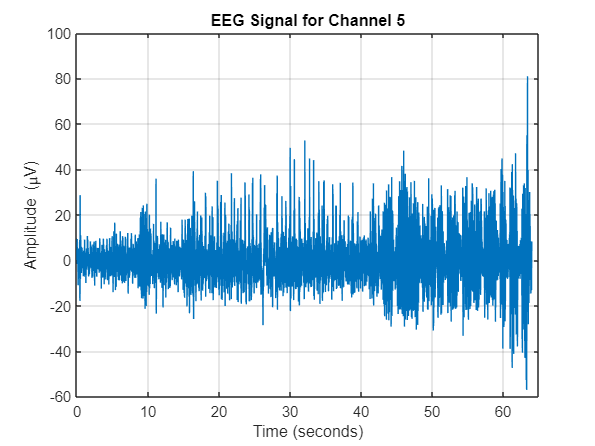

% EEG - 1
load('EEG_sig.mat');  
fs = des.samplingfreq;  

channel_number = 5;
signal = Z(channel_number, :);  
time = (0:length(signal)-1) / fs;

figure;
plot(time, signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
title(['EEG Signal for Channel ' num2str(channel_number)]);
grid on;

xlim([0, max(time) + 1]);

#### part 2)

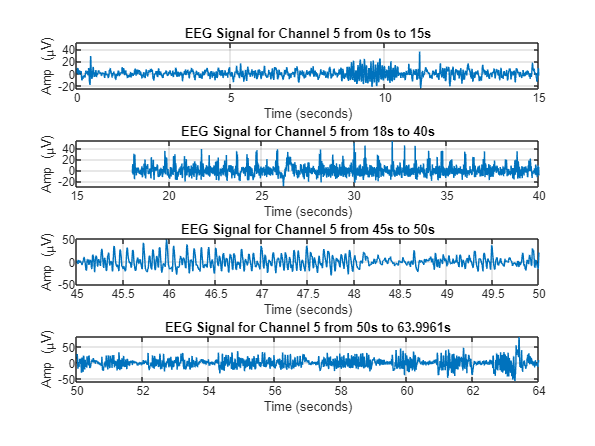

% EEG - 2
load('EEG_sig.mat');

fs = 256;
channel_number = 5;
signal = Z(channel_number, :);
signal_length = length(signal);

intervals = [0, 15; 18, 40; 45, 50 ; 50, max(time)];
num_intervals = size(intervals, 1);

figure;
for i = 1:num_intervals
    start_sample = max(1, round(intervals(i, 1) * fs));
    end_sample = min(signal_length, round(intervals(i, 2) * fs));
    segment = signal(start_sample:end_sample);
    time = (start_sample:end_sample) / fs;
    subplot(num_intervals, 1, i);
    plot(time, segment);
    xlabel('Time (seconds)');
    ylabel('Amp (\muV)');
    title(['EEG Signal for Channel ' num2str(channel_number) ' from ' num2str(intervals(i, 1)) 's to ' num2str(intervals(i, 2)) 's']);
    grid on;
end

the signal shows stronger spikes in the intervals [45,50] than other intervals

also the intervals [18,40] and [50,64] have stronger spikes than the interval [0,15]

generally we see more most activity of signals in the below order

- third part

- second part

- fourth part

- first part

#### part 3)

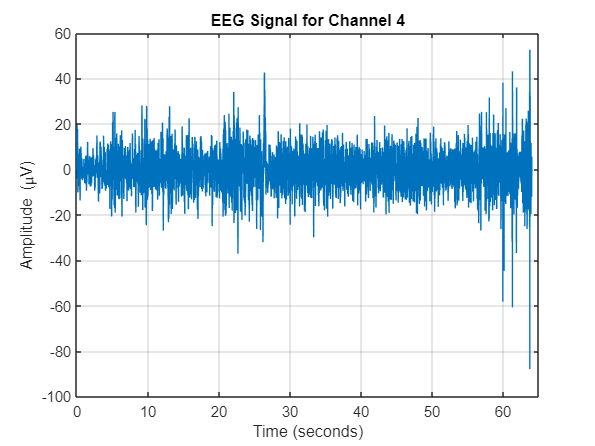

% EEG - 3
load('EEG_sig.mat');  
fs = des.samplingfreq;  

channel_number = 4;
signal = Z(channel_number, :);  
time = (0:length(signal)-1) / fs;

figure;
plot(time, signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
title(['EEG Signal for Channel ' num2str(channel_number)]);
grid on;

xlim([0, max(time) + 1]);

these signals dont look the same (channel 4,5)

since channel 5 is the center of event we see most changes on this channel.

#### part 4)

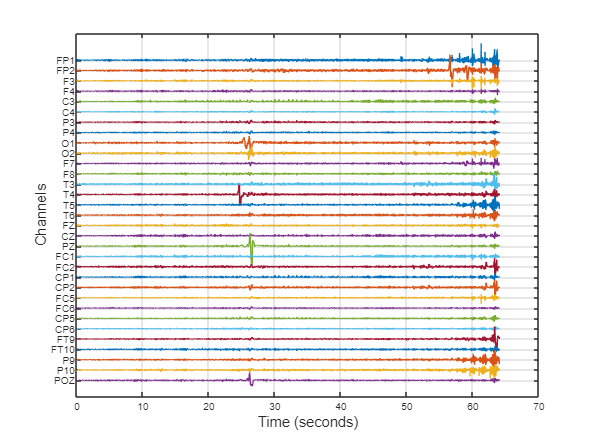

% EEG - 4
load('EEG_sig.mat');

offset = 2.5*max(max(abs(Z)))/5;
feq = 256;
ElecName = des.channelnames;

disp_eeg(Z,offset,feq,ElecName);

#### part 5)

in this part the red box is the pre seizure part of the signal where we start to see high frequency components 

and rhythmic spikes in the signal.

the green box is the seizure onset where we see sudden increase in high frequency components and we know 

this pattern includes rapid spikes which shows high activity in the neurons related to this section.

blue blox is post seizure activity section and we see slower patterns in the signal compared to last part 

#### part 6)

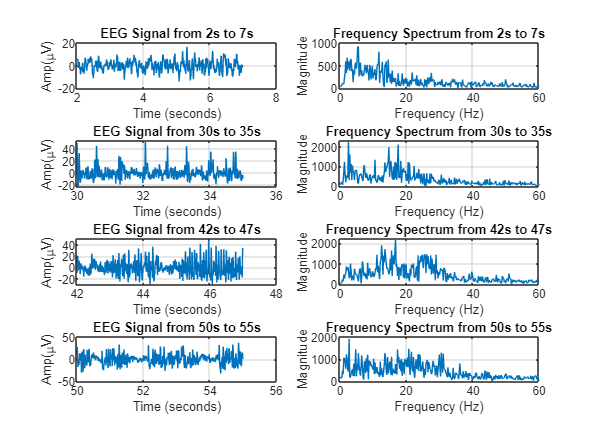

% EEG - 6
load('EEG_sig.mat');

fs = 256;  
channel_number = 5;  
signal = Z(channel_number, :);

segments = [2, 7; 30, 35; 42, 47; 50, 55];
num_segments = size(segments, 1);

figure;

for i = 1:num_segments
    start_sample = max(1, round(segments(i, 1) * fs));
    end_sample = min(length(signal), round(segments(i, 2) * fs));
    
    segment_signal = signal(start_sample:end_sample);
    time = (start_sample:end_sample) / fs;
    
    subplot(num_segments, 2, (i-1)*2 + 1);
    plot(time, segment_signal);
    xlabel('Time (seconds)');
    ylabel('Amp(\muV)');
    title(['EEG Signal from ' num2str(segments(i, 1)) 's to ' num2str(segments(i, 2)) 's']);
    grid on;
    
    N = length(segment_signal);
    f = (0:N-1) * (fs/N);
    segment_fft = abs(fft(segment_signal));
    
    subplot(num_segments, 2, (i-1)*2 + 2);
    plot(f, segment_fft);
    xlim([0 60]);  
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Spectrum from ' num2str(segments(i, 1)) 's to ' num2str(segments(i, 2)) 's']);
    grid on;
end

#### part 7)

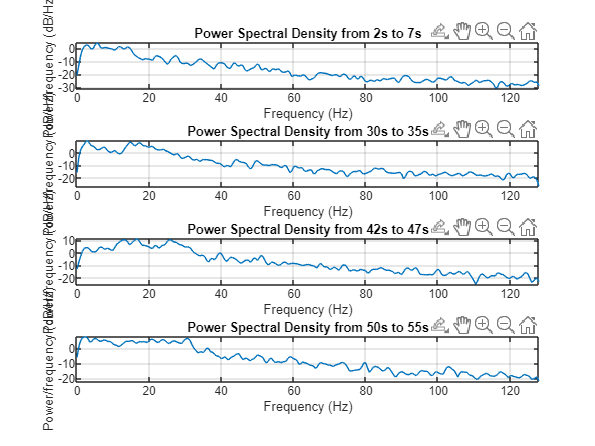

% EEG - 7
load('EEG_sig.mat');

fs = 256;  
channel_number = 5;
signal = Z(channel_number, :);

segments = [2, 7; 30, 35; 42, 47; 50, 55];
num_segments = size(segments, 1);

figure;

for i = 1:num_segments
    start_sample = max(1, round(segments(i, 1) * fs));
    end_sample = min(length(signal), round(segments(i, 2) * fs));
    
    segment_signal = signal(start_sample:end_sample);
    
    subplot(num_segments, 1, i);
    pwelch(segment_signal, [], [], [], fs);
    title(['Power Spectral Density from ' num2str(segments(i, 1)) 's to ' num2str(segments(i, 2)) 's']);
end

for the time interval [2,7] we see lower frequency components build up most of the signal 

and higher components are not of much importance. 

power/frequency for freq range 0-20 mostly around 0dB

power/frequency for freq range 20-40 mostly around -10dB

power/frequency for freq range 40-60 mostly around -15dB

for the time interval [30,35] we see stronger spikes and higher freq components compared

to previous section.

power/frequency for freq range 0-20 mostly around 10dB

power/frequency for freq range 20-40 mostly around -5dB

power/frequency for freq range 40-60 mostly around -10dB

for the time interval [42,47] we see strong spikes and higher freq components are getting stronger

this is the peek level of abnormalities

power/frequency for freq range 0-20 mostly around 10dB

power/frequency for freq range 20-40 mostly around 5dB

power/frequency for freq range 40-60 mostly around -5dB

for the time interval [50,55] we see the signal gets calmer and strong spikes start to fade away.

higher freq components have less power and we are getting closer to normal activity of the brain

power/frequency for freq range 0-20 mostly around 5dB

power/frequency for freq range 20-40 mostly around 0dB

power/frequency for freq range 40-60 mostly around -10dB

#### part 8)

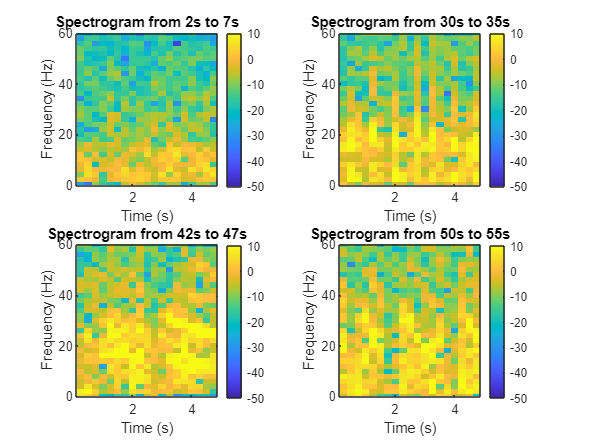

% EEG - 8
load('EEG_sig.mat');

fs = 256;  
channel_number = 5;
signal = Z(channel_number, :);

segments = [2, 7; 30, 35; 42, 47; 50, 55];
num_segments = size(segments, 1);
window_length = 128;  
noverlap = 64;  
nfft = 128;  
window = hamming(window_length);

figure;

for i = 1:num_segments
    start_sample = max(1, round(segments(i, 1) * fs));
    end_sample = min(length(signal), round(segments(i, 2) * fs));
    
    segment_signal = signal(start_sample:end_sample);
    
    subplot(2, 2, i);
    spectrogram(segment_signal, window, noverlap, nfft, fs, 'yaxis');
    title(['Spectrogram from ' num2str(segments(i, 1)) 's to ' num2str(segments(i, 2)) 's']);
    ylim([0 60]);  
    colorbar;
    caxis([-50 10]);
end

time interval [2,7] is low activity part of the signal where brain is calm.

we can say time interval [30,35] has higher freq components and stronger signals than [2,7] interval 

and also time interval [42,47] has higher freq components and stronger signals than [30,35] interval 

time interval [50,55] is composed of less high freq components compared to the time interval [42,47] of the signal

**part 9)**

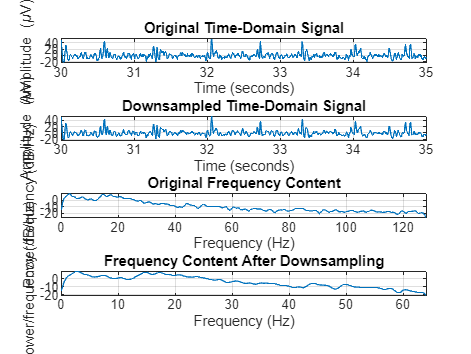

% EEG - 9
load('EEG_sig.mat');

fs = 256;  
channel_number = 5;  
signal = Z(channel_number, :);

start_sample = max(1, round(30 * fs));
end_sample = min(length(signal), round(35 * fs));
segment_signal = signal(start_sample:end_sample);
time_original = (start_sample:end_sample) / fs;

figure;
subplot(4, 1, 1);
plot(time_original, segment_signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
title('Original Time-Domain Signal');
grid on;

downsample_factor = 2;
fs_new = fs / downsample_factor;

fc = fs_new / 2;  % Nyquist frequency for the new sampling rate
[b, a] = butter(4, fc / (fs / 2));  % 4th-order Butterworth filter
filtered_signal = filtfilt(b, a, segment_signal);

downsampled_signal = downsample(filtered_signal, downsample_factor);
time_downsampled = (start_sample:downsample_factor:end_sample) / fs;

subplot(4, 1, 2);
plot(time_downsampled, downsampled_signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
title('Downsampled Time-Domain Signal');
grid on;

subplot(4, 1, 3);
pwelch(segment_signal, [], [], [], fs);
title('Original Frequency Content');

subplot(4, 1, 4);
pwelch(downsampled_signal, [], [], [], fs_new);
title('Frequency Content After Downsampling');

subplot(4,1,3)
xlim([0.0 128.0])

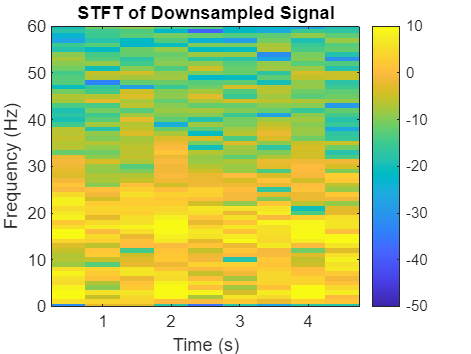


figure;
window_length = 128;
noverlap = 64;
nfft = 128;
window = hamming(window_length);
spectrogram(downsampled_signal, window, noverlap, nfft, fs_new, 'yaxis');
title('STFT of Downsampled Signal');
ylim([0 60]);
colorbar;
caxis([-50 10]);  

in the time domain we dont see much difference between downsampled signal and the original signal

in the frequency domain not much data is generally lost but because of less freq resolution,

the frequency content becomes smoother.

stft of both signals are almost the same

## **EOG Section**

**Part 1)**

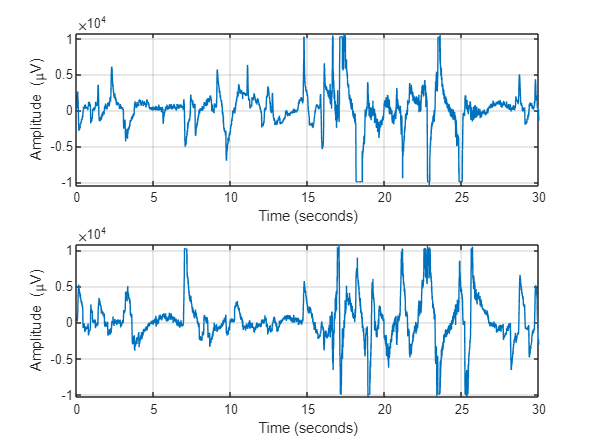

% EOG - 1
load('EOG_sig.mat');  

left_eye_signal = Sig(1, :);
right_eye_signal = Sig(2, :);
fs = 256;  
time = (0:length(left_eye_signal)-1) / fs;

% Plotting the time-domain signals
figure;
subplot(2, 1, 1);
plot(time, left_eye_signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
grid on;

subplot(2, 1, 2);
plot(time, right_eye_signal);
xlabel('Time (seconds)');
ylabel('Amplitude (\muV)');
grid on;

in this part we can say these two channels are in contrast to each other and they have different polarities

based on this information we can say we are either using the outer electrodes or the inner electrodes

but we cant say which ones we are using.

**Part 2)**

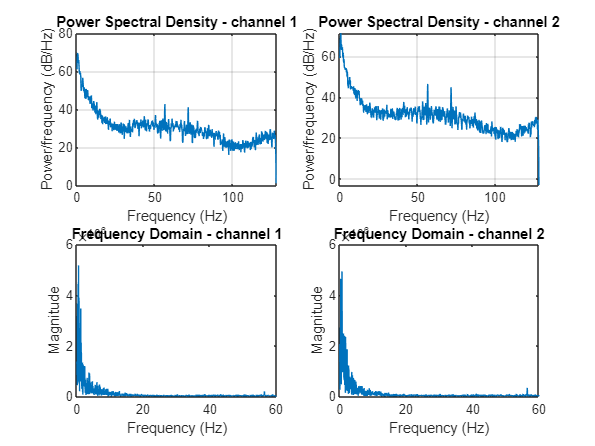

% EOG - 2
load('EOG_sig.mat');  

left_eye_signal = Sig(1, :);  
right_eye_signal = Sig(2, :);  
fs = 256;  

figure;
subplot(2, 2, 1);
pwelch(left_eye_signal, [], [], [], fs);
title('Power Spectral Density - channel 1');

subplot(2, 2, 2);
pwelch(right_eye_signal, [], [], [], fs);
title('Power Spectral Density - channel 2');

N = length(left_eye_signal);  
f = (0:N-1)*(fs/N);  

fft_left_eye = abs(fft(left_eye_signal));

fft_right_eye = abs(fft(right_eye_signal));

subplot(2, 2, 3);
plot(f, fft_left_eye);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - channel 1');
xlim([0 60]);  

subplot(2, 2, 4);
plot(f, fft_right_eye);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - channel 2');
xlim([0 60]);  

based on power spectral density of these signals we can say EOG signal is a powerful signal and causes a lot of noise.

based on the Fourier transform of the signal we can say that this signal is composed of low frequency components.